# PSP ASA PSPSP 2025 PS2

## Hohmann Transfer Practice

While plotting code is provided, we heavily suggest drawing diagrams for each problem so that you can make sure your answers make sense.

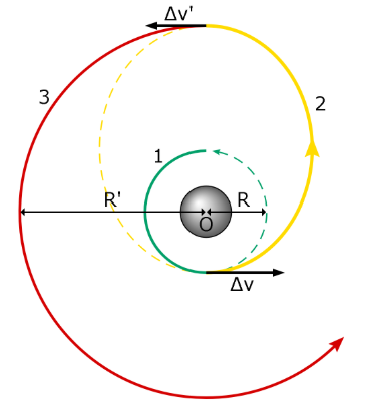

### Physical Constants (from *Table of Constants*)

R_E = 6378.1363; % [km] Earth radius
mu_E = 398600.4415; % [km3 / s2] Earth gravitational parameter

R_mn = 1738.2; % [km] Moon radius
mu_mn = 4902.8005821478; % [km3 / s2] Moon gravitational parameter

### Problem 1 - Geostationary Satellite Inspection at the ISS

Alice is on a mission to retrieve a satellite from geostationary orbit and bring it to the ISS for detailed inspection. The rocket launch is scheduled so that a Hohmann transfer will make Alice rendezvous with the satellite. However, NASA forgot to think about how she will get to the ISS so they have asked you to plan the ISS redezvous.

### Problem 1.1 - Launch to Geostationary Orbit

Starting from the Earth's surface, design a trajectory to get Alice to geostationary orbit using a Hohmann transfer. The true anomaly when you launch is 0 degrees.

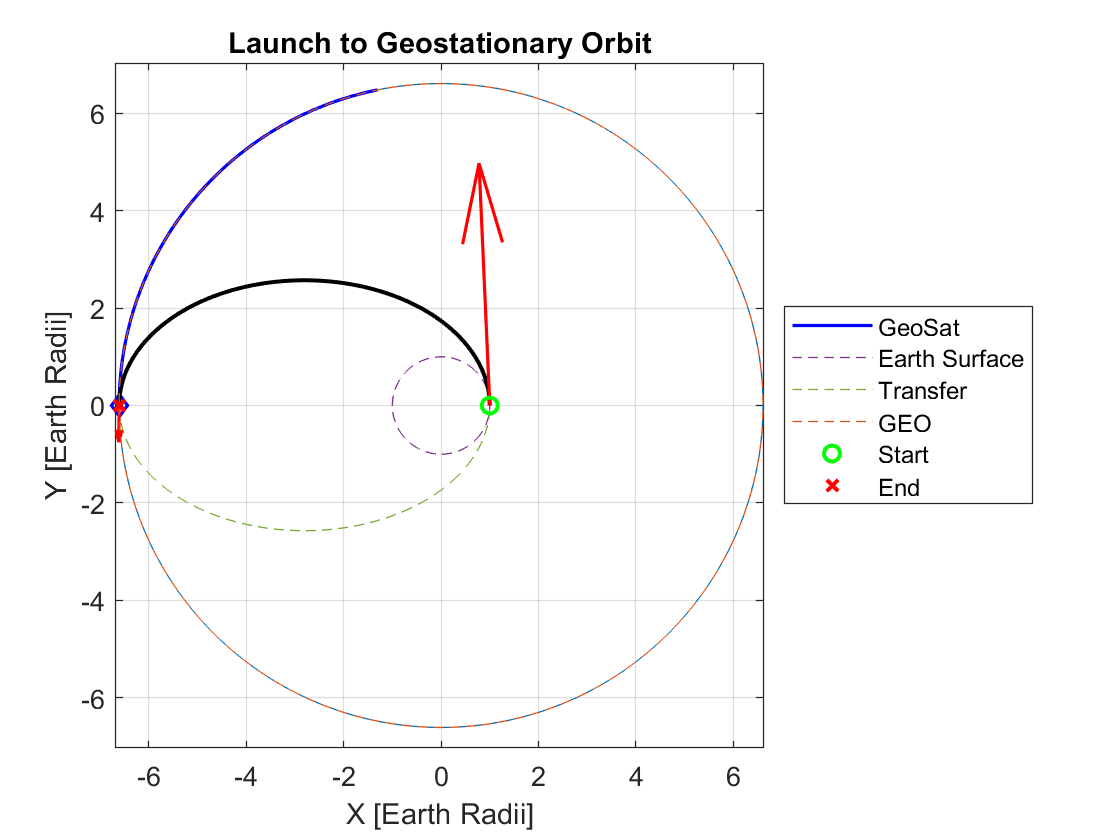

#### Given Values

h_geo = 35786; % [km] geostationary altitude
h_park = 0; % [km] parking orbit altitude
thetastar_0_sc = 0; % [deg] initial true anomaly

#### a) Calculate the period of the transfer orbit. Geostationary transfer orbits usually have periods around 10.5 hours, is yours close (within 3 minutes)?

r_geo = h_geo + R_E;
r_park = h_park + R_E;
r_p_trans = r_park;
r_a_trans = r_geo;
a_trans = (r_p_trans + r_a_trans) / 2;
P_trans = 2 * pi * sqrt(a_trans ^ 3 / mu_E)

P_trans = 3.7631e+04

#### b) Calculate the delta V needed for this transfer. How much does including the help from the Earth's rotation at launch help? (use the value for Axial Rotation Period in the *Table of Constants*)

v_park = sqrt(mu_E / r_p_trans);

v_p_trans = sqrt(mu_E * (2 / r_p_trans - 1 / a_trans));
v_a_trans = sqrt(mu_E * (2 / r_geo - 1 / a_trans));
v_geo = sqrt(mu_E / r_geo);

axial_rot_period_E = 1.0027368; % [rev / day]
w_E = axial_rot_period_E * 2 * pi / (60 * 60 * 24); % [rad / s]
v_tang_E = R_E * w_E;

dV_1 = v_p_trans - v_tang_E;
dV_2 = v_geo - v_a_trans;

dV_total = sqrt(dV_2 ^ 2 + dV_1 ^ 2);

dV_total_adj_save_perc = 100 - dV_total / (dV_total - v_tang_E) * 100;

#### c) What is the true anomaly of the geostationary satellite at Alice's launch?

n_geo = sqrt(mu_E / r_geo ^ 3); % [rad / s]
thetastar_geo_0 = rad2deg(pi - n_geo * P_trans / 2)

thetastar_geo_0 = 101.3873

#### d) Plot the transfer using the provided plotting code

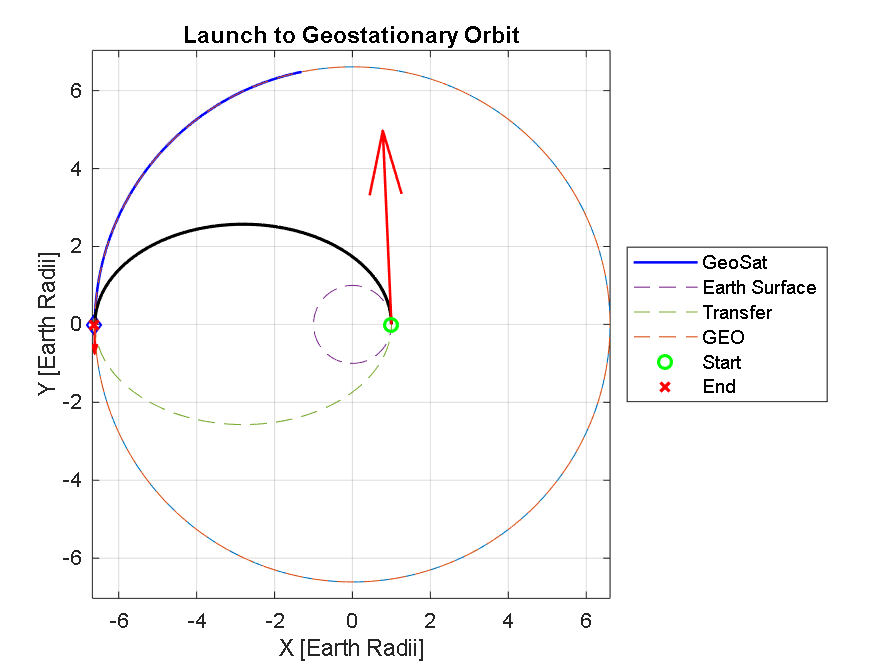

e_trans = r_geo / a_trans - 1;

ae_sc = [r_park, a_trans, r_geo; 
         0, e_trans, 0];
objects_1a = struct();
objects_1a.a = r_geo;
objects_1a.e = 0;
objects_1a.w = deg2rad(thetastar_geo_0);
objects_1a.c = "b";
objects_1a.t_max = -1;
objects_1a.name = "GeoSat";
delta_v_1a = [dV_1, dV_2];
plot_Hohmann_transfer(0, ae_sc, ["Earth Surface", "Transfer", "GEO"], [0, P_trans / 2, 0], delta_v_1a, objects_1a, mu_E, 200, "Launch to Geostationary Orbit", R_E, "Earth Radii")

### Problem 1.2 - ISS Redezvous from Geostationary Orbit

The International Space Station has a true anomaly of 60 degrees when Alice launches. Construct a Hohmann transfer so Alice rendezvoused with the ISS.

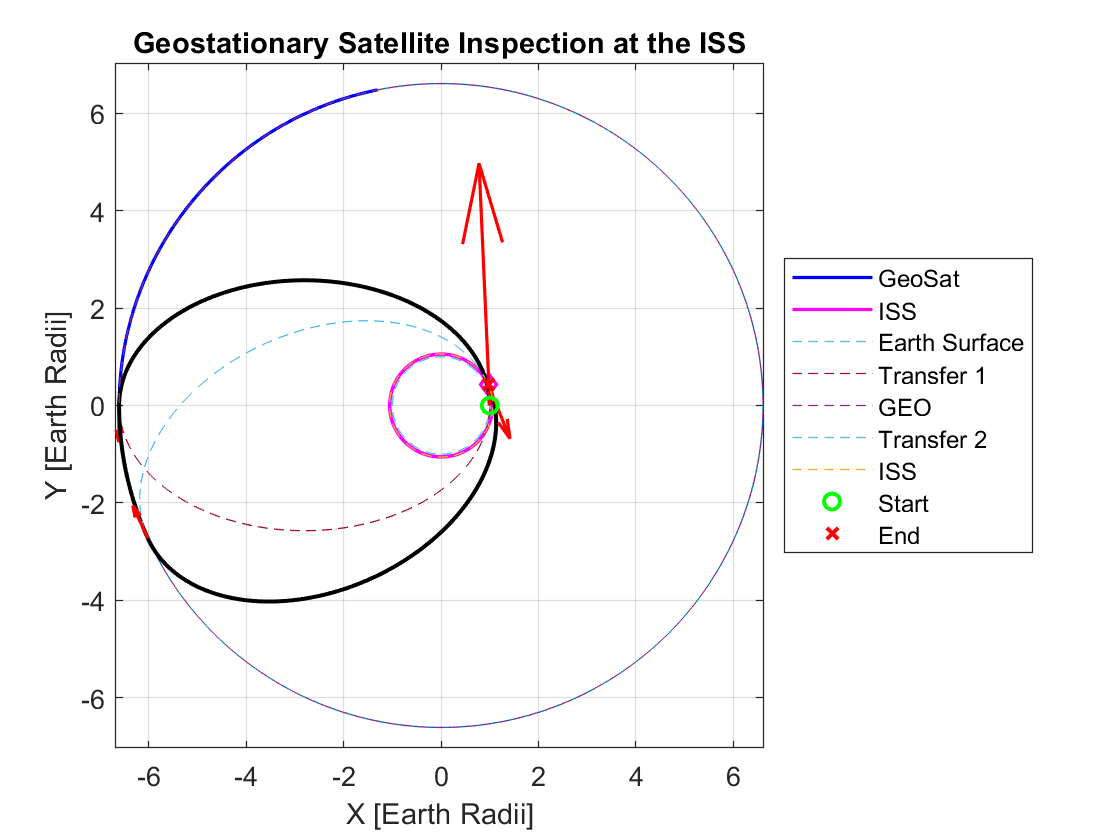

#### Given Values

h_ISS = 378.5; % [km] circular approximation of height ISS orbits at
thetastar_0_ISS = 60; % [deg] 

#### a) What is the true anomaly of the ISS when Alice meets the geostationary satellite?

r_ISS = h_ISS + R_E;
n_ISS = sqrt(mu_E / r_ISS ^ 3);
thetastar_geo_ISS = mod(rad2deg(deg2rad(thetastar_0_ISS) + n_ISS * P_trans / 2), 360)

thetastar_geo_ISS = 205.4959

#### b) Calculate the Hohmann transfer to the ISS. How much delta V is needed?

a_ISS_trans = (r_geo + r_ISS) / 2;
e_trans_ISS = r_geo / a_ISS_trans - 1;

v_ISS = sqrt(mu_E / r_ISS);

v_p_trans = sqrt(mu_E * (2 / r_ISS - 1 / a_ISS_trans));
v_a_trans = sqrt(mu_E * (2 / r_geo - 1 / a_ISS_trans));

dV_1 = v_a_trans - v_geo;
dV_2 = v_ISS - v_p_trans;

dV_total = sqrt(dV_1 ^ 2 + dV_2 ^ 2);

#### c) How long must Alice wait before performing the Hohmann transfer so that she successfully rendezvouses with the ISS?

P_ISS_trans = 2 * pi * sqrt(a_ISS_trans ^ 3 / mu_E);
% How many degrees does the ISS travel during the transfer?
deltathetastar_ISS = mod(rad2deg(P_ISS_trans / 2 * n_ISS), 360)

deltathetastar_ISS = 159.8572

% How far is the ISS from being in the right place for the transfer?
thetastar_geo_diff = mod(deltathetastar_ISS + thetastar_geo_ISS, 360)

thetastar_geo_diff = 5.3531

% Relative speed of ISS relative to geostationary satellite
rel_n = n_ISS - n_geo;
% How much time until a transfer can happen?
T_wait = (2 * pi - deg2rad(thetastar_geo_diff)) / rel_n;
T_wait_hr = T_wait / 60 / 60

T_wait_hr = 1.6162

#### d) Plot Alice's mission using the provided plotting code

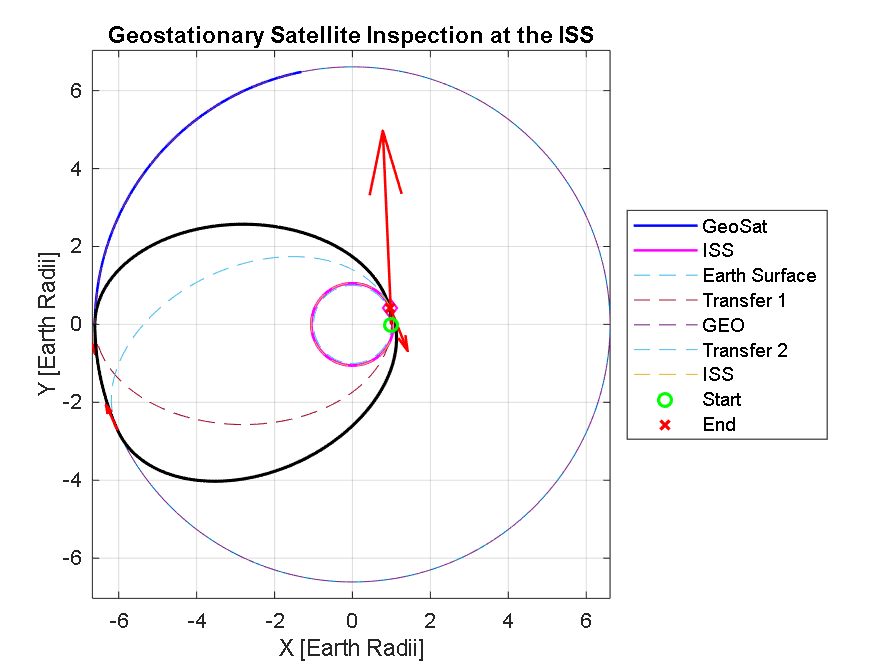

ae_sc = [r_park, a_trans, r_geo, a_ISS_trans, r_ISS; 
         0, e_trans, 0, e_trans_ISS, 0];
objects_1 = struct();
objects_1.a = [r_geo, r_ISS];
objects_1.e = [0, 0];
objects_1.w = [deg2rad(thetastar_geo_0), deg2rad(thetastar_0_ISS)];
objects_1.c = ["b", "m"];
objects_1.t_max = [P_trans / 2, -1];
objects_1.name = ["GeoSat", "ISS"];
delta_v_1 = [delta_v_1a, dV_1, dV_2];
plot_Hohmann_transfer(0, ae_sc, ["Earth Surface", "Transfer 1", "GEO", "Transfer 2", "ISS"], [0, P_trans / 2, T_wait, P_ISS_trans / 2, 0], delta_v_1, objects_1, mu_E, 200, "Geostationary Satellite Inspection at the ISS", R_E, "Earth Radii")

### Problem 2 - Injection into Low Lunar Orbit 

Bob is visiting the Moon for a holiday and is currently in a hyperbolic orbit with an eccentricity of 1.25 and a perilune altitude of 400 km. Create a Hohmann transfer between the hyperbolic flyby trajectory and a circular parking orbit with an altitude of 110 km (Bob's first burn will happen at the perilune of the hyperbolic trajectory).

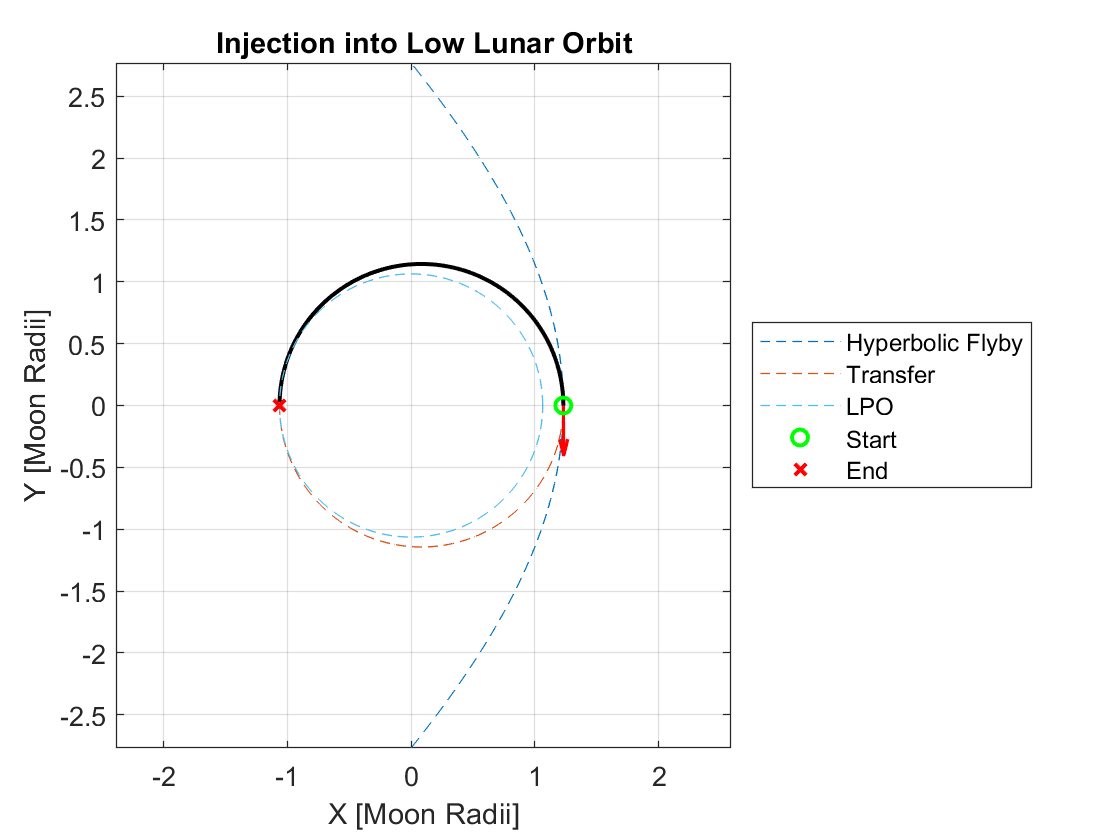

#### Given Values

e_hyp = 1.25; % [] eccentricity of hyperbolic flyby trajectory
h_p_hyp = 400; % [km] perilune of hyperbolic flyby trajectory
h_LPO = 110; % [km] altitude of (planned) lunar parking orbit for Apollo 11 at time of rendezvous

#### a) What is Bob's velocity at the perilune of the hyperbolic flyby trajectory?

r_p_hyp = h_p_hyp + R_mn;
a_hyp = r_p_hyp / (1 - e_hyp)

a_hyp = -8.5528e+03

v_p_hyp = sqrt(mu_mn * (-1 / a_hyp + 2 / r_p_hyp))

v_p_hyp = 2.2714

#### b) What would the velocity of a circular orbit with the same altitude as the perilune of Bob's flyby trajectory be? A hyperbolic trajectory will always have a velocity greater than $\sqrt{2}$ times the velocity of a circular orbit with the same radius, check your answer with this knowledge.

v_c_hyp_p = sqrt(mu_mn / r_p_hyp) * sqrt(2)

v_c_hyp_p = 2.1415

#### c) Create the Hohmann transfer that gets Bob into the parking orbit. What is the delta V Bob needs?

r_LPO = h_LPO + R_mn;
v_LPO = sqrt(mu_mn / r_LPO);

a_trans = (r_p_hyp + r_LPO) / 2

a_trans = 1.9932e+03


e_trans = r_p_hyp / a_trans - 1

e_trans = 0.0727

P_trans = 2 * pi * sqrt(a_trans ^ 3 / mu_mn)

P_trans = 7.9852e+03


v_a_trans = sqrt(mu_mn * (2 / r_p_hyp - 1 / a_trans));
v_p_trans = sqrt(mu_mn * (2 / r_LPO - 1 / a_trans));

dV_1 = v_a_trans - v_p_hyp

dV_1 = -0.8132

dV_2 = v_LPO - v_p_trans

dV_2 = -0.0582


dV_total = sqrt(dV_1 ^ 2 + dV_2 ^ 2)

dV_total = 0.8153

#### d) Plot Bob's transfer using the provided plotting code

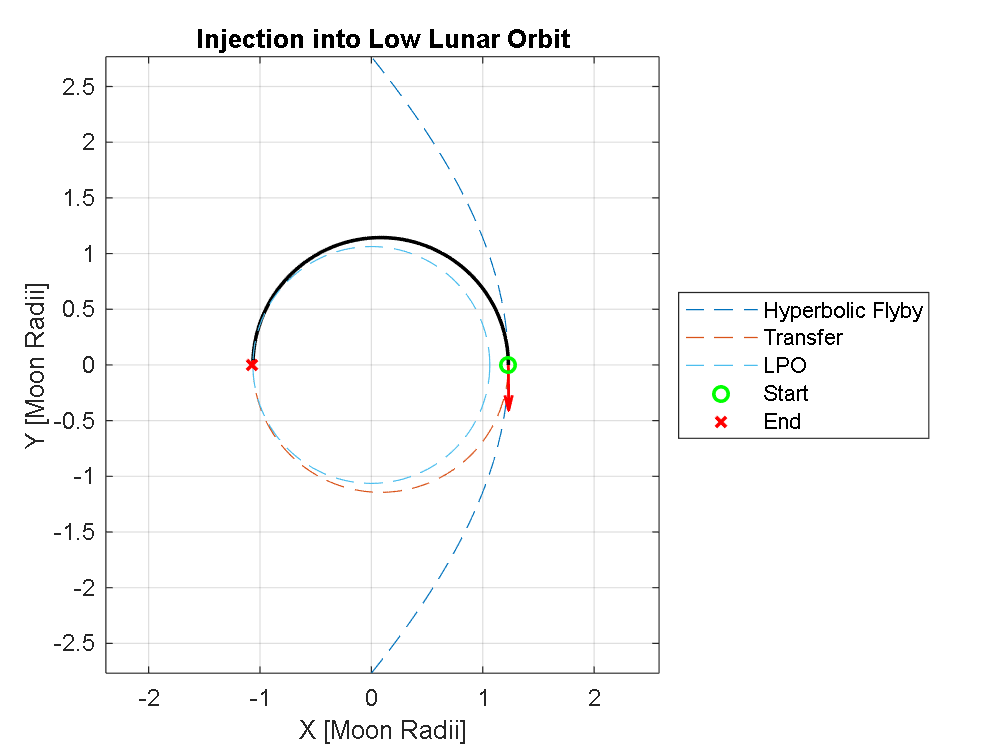

ae_sc = [a_hyp, a_trans, r_LPO; 
         e_hyp, e_trans, 0];
objects_2 = struct();
objects_2.a = [];
objects_2.e = [];
objects_2.w = [];
objects_2.c = [];
objects_2.t_max = [];
objects_2.name = [];
delta_v_2 = [dV_1, dV_2];
plot_Hohmann_transfer(0, ae_sc, ["Hyperbolic Flyby", "Transfer", "LPO"], [0, P_trans / 2, 0], delta_v_2, objects_2, mu_mn, 200, "Injection into Low Lunar Orbit", R_mn, "Moon Radii")